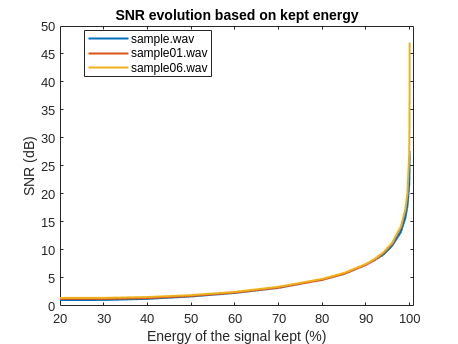

% SNR with change of energy values of samples

% 32 bit coefficients so no loss from their quantization

x = [ 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.85 0.9 0.92 0.94 0.96 0.98 0.99 0.995 0.999 0.9995 0.9999 0.99999];
x = x .* 100;
y = [ 1.0753 1.084 1.2813 1.70589 2.33001 3.23915 4.67293 5.71584 7.32817 8.18806 9.18892 10.7736 13.2318 15.6879 17.9192 21.6323 23.1584 26.551 27.6534];
y6 = [ 1.43864 1.45212 1.59692 1.94241 2.51553 3.43024 4.8347 5.89813 7.50051 8.39104 9.57555 11.2669 14.2045 17.165 20.1422 27.1061 30.1112 37.0883 47.0409];
y1 = [ 1.26127 1.27212 1.40398 1.78355 2.38486 3.27578 4.66217 5.73739 7.32244 8.22339 9.41013 11.1113 14.0595 17.0394 20.0335 27.0054 30.0124 37.001 47.0104];

p = plot(x,y, x, y1, x, y6);
legend("sample.wav", "sample01.wav", "sample06.wav", "Location","best");
xlim([20  101]);
title("SNR evolution based on kept energy");
xlabel("Energy of the signal kept (%)");
ylabel("SNR (dB)");
p(1).LineWidth = 1.5;
p(2).LineWidth = 1.5;
p(3).LineWidth = 1.5;

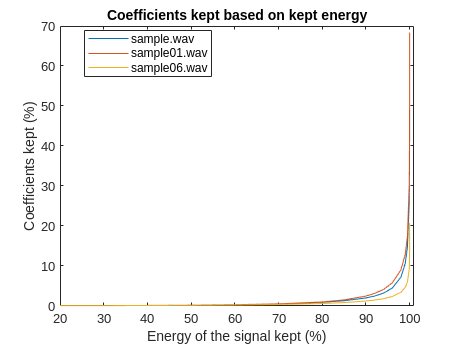


y2 = [ 0.0976562 0.100206 0.139873 0.210046 0.32508 0.528893 0.937084 1.31656 2.0165 2.49156 3.21028 4.45422 7.20427 10.6745 14.7341 25.6673 30.6921 42.4247 58.0701];
y12 = [0.0976562 0.101906 0.130685 0.195583 0.309077 0.527915 1.01496 1.52175 2.49089 3.15258 4.13475 5.74812 9.03857 12.9349 17.4094 30.0592 36.3002 51.0629 68.3333];
y62 = [0.0976091 0.100109 0.118084 0.161675 0.237158 0.369773 0.623585 0.853619 1.24236 1.4823 1.82263 2.35955 3.44618 4.68896 6.00619 9.15841 10.5353 13.8616 20.7902];

p2 = plot(x, y2, x, y12, x, y62);
xlim([20  101]);
title("Coefficients kept based on kept energy");
legend("sample.wav", "sample01.wav", "sample06.wav", "Location","best");
xlabel("Energy of the signal kept (%)");
ylabel("Coefficients kept (%)");

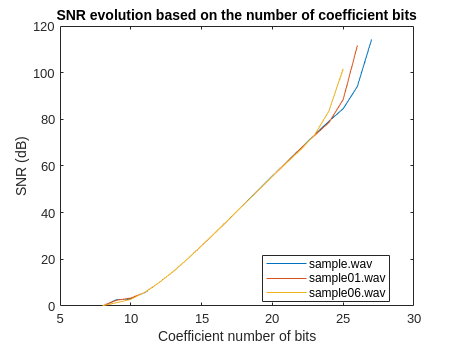

% SNR with change of coefficient bits

% keep all energy so we can see how the SNR evolves
% blocksize = 1024;

x = (8:27);
y1 = [ 0.0575586 2.47658 3.418 5.85593 10.0899 14.7957 20.13 25.8127 31.6338 37.6024 43.5589 49.5701 55.5988 61.5782 67.5167 73.2042 78.7174 88.5018 111.591 inf];
y6 = [ 0.0929087 1.42063 2.86596 5.94421 10.0559 14.8317 20.1222 25.8555 31.7091 37.6411 43.5731 49.5414 55.5382 61.373 67.0325 73.5195 83.6658 101.702 inf inf];
y = [ 0.0254706 2.69944 3.03014 5.80103 10.0877 14.7953 20.1324 25.8613 31.6918 37.6584 43.6479 49.6579 55.7006 61.658 67.5825 73.4916 79.2233 84.5818 94.1097 114.17 ];

plot(x, y, x, y1, x, y6);
title("SNR evolution based on the number of coefficient bits");
legend("sample.wav", "sample01.wav", "sample06.wav", "Location","best");
xlabel("Coefficient number of bits");
ylabel("SNR (dB)");

% compression ratios for 16 and 22 bits